clear
clc

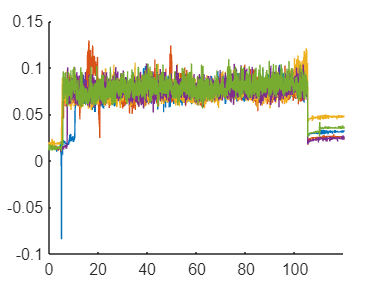

directory = 'data\friction-experiment\without-skin\static-friction';
files = dir([directory '\*.csv']);

figure;
hold on
for i = 1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = readtable(file);
    plot(data.Var1,data.Var2)
end
hold off

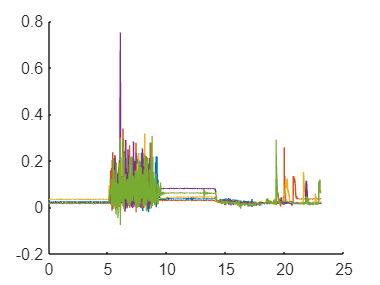


figure;
hold on
directory = 'data\friction-experiment\without-skin\dynamic-friction';
files = dir([directory '\*.csv']);

for i = 1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = readtable(file);
    plot(data.Var1,data.Var2)
end
hold off

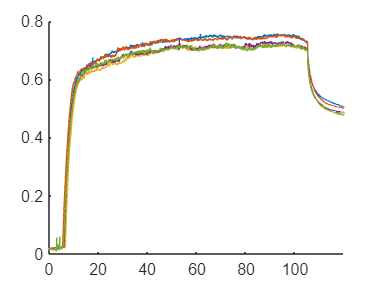

directory = 'data\friction-experiment\with-skin\static-friction';
files = dir([directory '\*.csv']);

figure;
hold on
for i = 1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = readtable(file);
    plot(data.Var1,data.Var2)
end
hold off

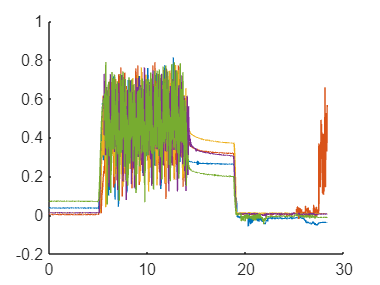


figure;
hold on
directory = 'data\friction-experiment\with-skin\dynamic-friction';
files = dir([directory '\*.csv']);

for i = 1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = readtable(file);
    plot(data.Var1,data.Var2)
end
hold off

directory = 'data\friction-experiment\with-skin\static-friction';
[static_with_skin, t1, static_with_skin_results] = extract_friction_data(directory,5001,10001,false);
directory = 'data\friction-experiment\with-skin\dynamic-friction';
[dynamic_with_skin, t2, dynamic_with_skin_results] = extract_friction_data(directory,540,1410,false);
directory = 'data\friction-experiment\without-skin\static-friction';
[static_without_skin, t3, static_without_skin_results] = extract_friction_data(directory,1070,10001,false);
directory = 'data\friction-experiment\without-skin\dynamic-friction';
[dynamic_without_skin, t4, dynamic_without_skin_results] = extract_friction_data(directory,540,901,false);

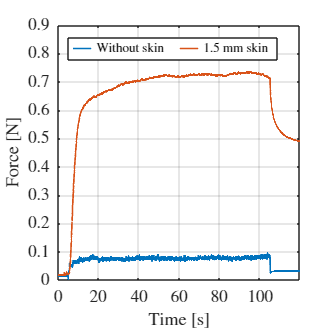

mean_static_without_skin = mean(static_without_skin);
mean_static_with_skin = mean(static_with_skin);
figure()
hold on
x0=10;
y0=10;
w=7;
h=7;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);

plot(t3,mean_static_without_skin,'Color',"#0072BD",'LineWidth',1)
plot(t3,mean_static_with_skin,'Color',"#D95319",'LineWidth',1)

lgnd = legend('Without skin','1.5 mm skin','Interpreter','latex','location','northwest','Orientation','horizontal');
lgnd.ItemTokenSize(1) = 11;
fontsize(10,'points')
fontsize(lgnd,8,'points')
yticks(0:0.1:1.2)
xticks(0:20:120)
ylim([0 0.9])
ylabel("Force [N]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

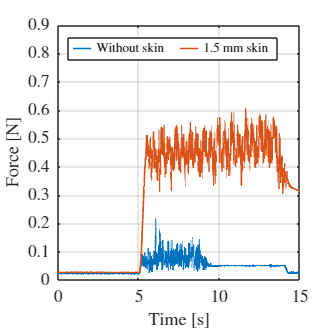

mean_dynamic_without_skin = mean(dynamic_without_skin);
mean_dynamic_with_skin = mean(dynamic_with_skin);
figure()
hold on
x0=10;
y0=10;
w=7;
h=7;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);

plot(t4,mean_dynamic_without_skin,'LineWidth',1)
plot(t2,mean_dynamic_with_skin,'LineWidth',1)

lgnd = legend('Without skin','1.5 mm skin','Interpreter','latex','location','northwest','Orientation','horizontal');
lgnd.ItemTokenSize(1) = 11;
fontsize(10,'points')
fontsize(lgnd,8,'points')
yticks(0:0.1:1)
ylim([0 0.9])
xlim([0 15])
ylabel("Force [N]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

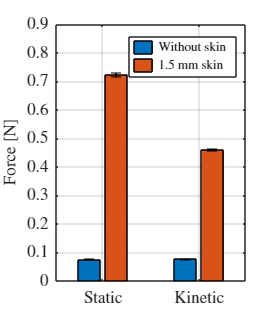

f_mean = [static_without_skin_results.amean static_with_skin_results.amean;
          dynamic_without_skin_results.amean dynamic_with_skin_results.amean];
f_se = [static_without_skin_results.ase static_with_skin_results.ase;
        dynamic_without_skin_results.ase dynamic_with_skin_results.ase];

b = figure;
figure(b);
hold on
bh = bar(f_mean);
%bh(2).FaceColor = [0.4660 0.6740 0.1880];
set(gca, 'XTickLabel', {'Static' 'Kinetic'});
set(gca,'TickLabelInterpreter','latex')
set(gca,'XTick',[1 2])
%set(gca,'YTick',[0 5 10 15])
ylim([0 0.85])
ylabel('Force [N]','Interpreter','latex')
fontsize(10,'points')

ngroups = size(f_mean, 1);
nbars = size(f_mean, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, f_mean(:,i), f_se(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=5.75;
h=6.68;
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('Without skin', '1.5 mm skin','Interpreter','latex');
lgnd.ItemTokenSize(1) = 11;
fontsize(10,'points')
fontsize(lgnd,8,'points')
ylim([0 0.9])
yticks(0:0.1:1)
grid on
box on
hold off

[h,p,ci,stats] = ttest(static_with_skin_results.i,static_without_skin_results.i)

h = 1

p = 1.1816e-07

ci =     0.6108    0.6524


stats = struct with fields:
    tstat: 84.3954
       df: 4
       sd: 0.0167


[h,p,ci,stats] = ttest(dynamic_with_skin_results.i,dynamic_without_skin_results.i)

h = 1

p = 1.4115e-04

ci =     0.2902    0.4307


stats = struct with fields:
    tstat: 14.2424
       df: 4
       sd: 0.0566


[h,p,ci,stats] = ttest(static_with_skin_results.a,static_without_skin_results.a)

h = 1

p = 1.3368e-07

ci =     0.6265    0.6705


stats = struct with fields:
    tstat: 81.8305
       df: 4
       sd: 0.0177


[h,p,ci,stats] = ttest(dynamic_with_skin_results.a,dynamic_without_skin_results.a)

h = 1

p = 1.0987e-07

ci =     0.3701    0.3948


stats = struct with fields:
    tstat: 85.9450
       df: 4
       sd: 0.0099


100*(static_with_skin_results.imean-static_without_skin_results.imean)/static_without_skin_results.imean

ans = 861.9519

100*(dynamic_with_skin_results.imean-dynamic_without_skin_results.imean)/dynamic_without_skin_results.imean

ans = 503.6654

100*(static_with_skin_results.amean-static_without_skin_results.amean)/static_without_skin_results.amean

ans = 853.8387

100*(dynamic_with_skin_results.amean-dynamic_without_skin_results.amean)/dynamic_without_skin_results.amean

ans = 495.7089

intercept_mean = mean(f_intercept)

intercept_mean = 0.6673

intercept_std = std(f_intercept)

intercept_std = 0.0160

intercept_se = std(f_intercept)/sqrt(length(f_intercept))

intercept_se = 0.0071


avg_mean = mean(f_avg)

avg_mean = 0.7122

avg_std = std(f_avg)

avg_std = 0.0166

avg_se = std(f_avg)/sqrt(length(f_avg))

avg_se = 0.0074

skin_T = 1.5; %mm
skin_iw = 34; %mm
skin_ew = skin_iw + skin_T; %mm
skin_ih = 21.75; %mm
skin_eh = skin_ih + skin_T; %mm
skin_L = 176; %mm
junction_w = 32.5; %mm
junction_h = 20; %mm
junction_T = 3; %mm
ecoflex50_d = 0.00107; %g/mm³
g = 9.82; %m/s^2
sledge_m = 7.78; %g

skin_V = (skin_ew*skin_eh*skin_L)-(skin_iw*skin_ih*skin_L) %mm^3

skin_V = 15114

junction_V = junction_w*junction_h*junction_T %mm^3

junction_V = 1950


skin_W = skin_V*ecoflex50_d %g

skin_W = 16.1720

junction_W = junction_V*ecoflex50_d %g

junction_W = 2.0865


robot_m_without = 62.34 %g

robot_m_without = 62.3400

robot_m_with = robot_m_without + skin_W + junction_W + sledge_m%g

robot_m_with = 88.3785


robot_W_without = robot_m_without/1000 * g

robot_W_without = 0.6122

robot_W_with = robot_m_with/1000 * g

robot_W_with = 0.8679


static_friction_coeff_without = static_without_skin_results.a / robot_W_without;
static_friction_coeff_without_mean = mean(static_friction_coeff_without)

static_friction_coeff_without_mean = 0.1241

static_friction_coeff_without_se = std(static_friction_coeff_without)/sqrt(length(static_friction_coeff_without))

static_friction_coeff_without_se = 0.0013

static_friction_coeff_with = static_with_skin_results.a / robot_W_with;
static_friction_coeff_with_mean = mean(static_friction_coeff_with)

static_friction_coeff_with_mean = 0.8347

static_friction_coeff_with_se = std(static_friction_coeff_with)/sqrt(length(static_friction_coeff_with))

static_friction_coeff_with_se = 0.0087



dynamic_friction_coeff_without = dynamic_without_skin_results.a / robot_W_without;
dynamic_friction_coeff_without_mean = mean(dynamic_friction_coeff_without)

dynamic_friction_coeff_without_mean = 0.1260

dynamic_friction_coeff_without_se = std(dynamic_friction_coeff_without)/sqrt(length(dynamic_friction_coeff_without))

dynamic_friction_coeff_without_se = 0.0017

dynamic_friction_coeff_with = dynamic_with_skin_results.a / robot_W_with;
dynamic_friction_coeff_with_mean = mean(dynamic_friction_coeff_with)

dynamic_friction_coeff_with_mean = 0.5295

dynamic_friction_coeff_with_se = std(dynamic_friction_coeff_with)/sqrt(length(dynamic_friction_coeff_with))

dynamic_friction_coeff_with_se = 0.0044